## Úloha 2: Potlačení akustického echa (simulace)

V souboru `echocancelation.mat` je signál **mic**, který simuluje záznam mužského hlasu na mikrofonu rušený jiným hlasem (ženským). V proměnné **ref** je referenční signál ženského hlasu. Použijte LMS filtr k potlačení ženského hlasu v záznamu mužského hlasu.

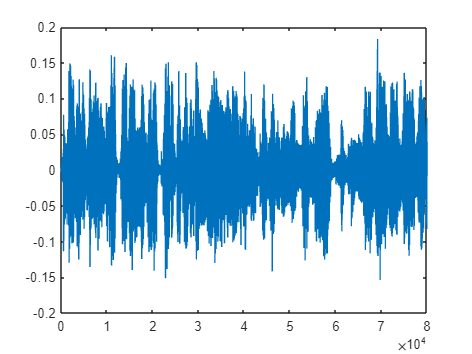

clc; clear all; close all;
load("echocancelation.mat")
plot(mic)

mic = speech + conv(a, ref)

e = mic - conv(w, ref)

corr(mic, ref) = corr(speech, ref) + corr(conv(a, ref), ref)

corr(speech, ref) usually zero

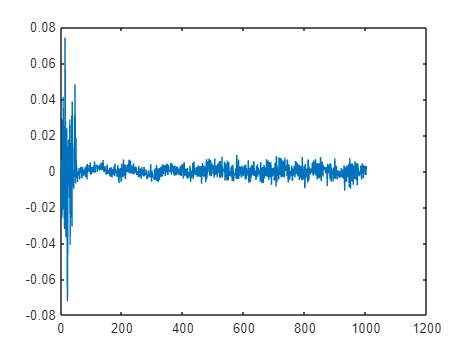

w = miso_firwiener(1000, ref', mic');
plot(w)

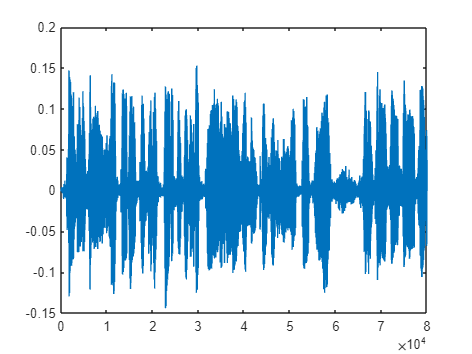


y_ref = filter(w, 1, ref);
e = mic - y_ref;
plot(e)

soundsc(e, fs)